IOrig = imread("muenzenVerdeckung.jpg");
imshow(IOrig);

d = drawline;
pos = d.Position;
diffPos = diff(pos);
diameter = round(hypot(diffPos(1), diffPos(2)));

[centers, radii] = imfindcircles(IOrig, [round(diameter * 0.25), diameter], ...
    "EdgeThreshold", 0.25, "Sensitivity", 0.97);


centers

centers = 1.0e+03 *

    0.5034    0.4012
    0.7248    0.3423
    0.9525    0.1052
    0.9684    0.6446
    0.4630    0.3042
    0.3734    0.0841
    1.1080    0.2573
    1.0754    0.4671
    0.7260    0.1014
    0.5272    0.5465


radii

radii =    88.9593
  117.6439
  103.7518
   78.8399
  114.0766
  110.2952
   79.5988
  117.4038
  111.7076
  115.9422


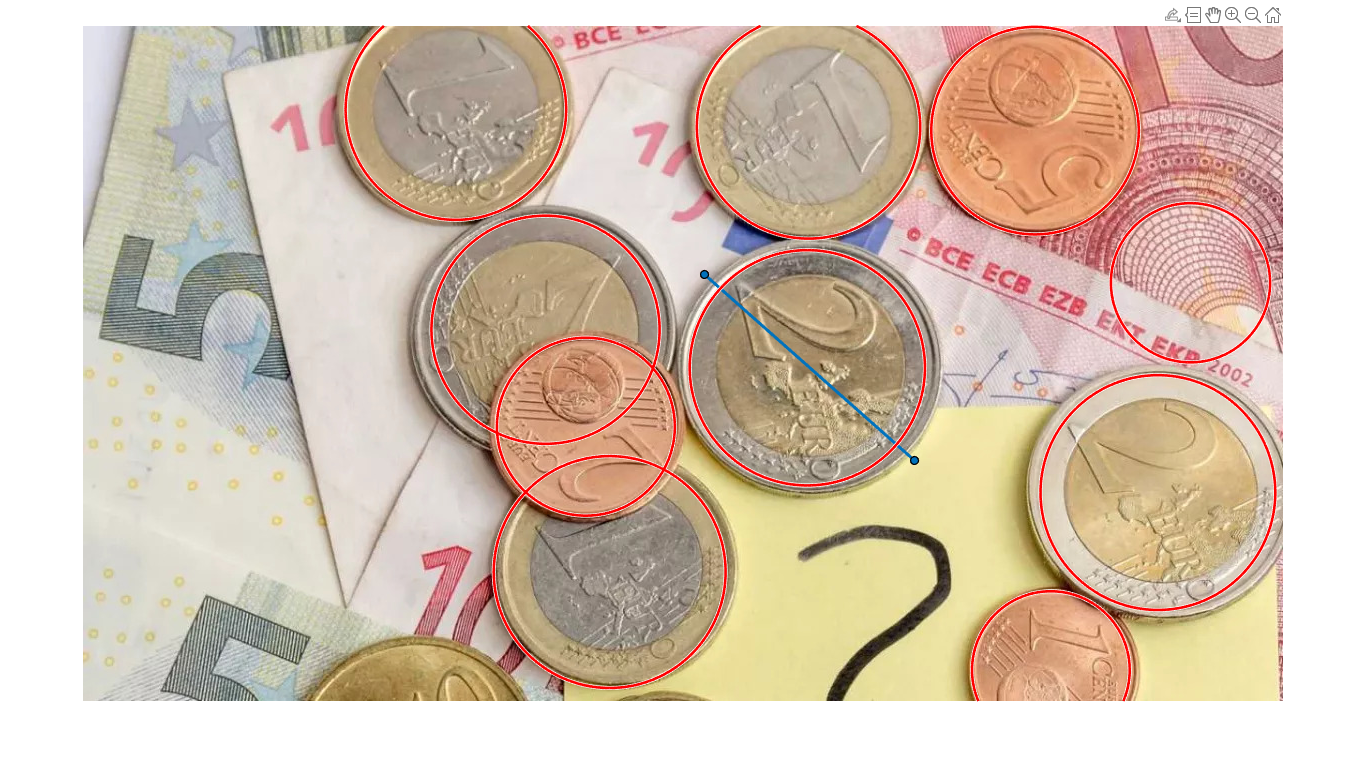

viscircles(centers, radii);


IPadded = padarray(IOrig, [500, 500], 0, 'both');

coinCount = size(centers, 1);

%coins = zeros(1, coinCount)

for i = 1:coinCount
    x = round(centers(i, 1)) - 20;
    y = round(centers(i, 2)) - 20;
    r = round(radii(i));
    coins[i] = imcrop(IOrig, [x - r, y - r, 2 * r + 20, 2* r + 20]); %Not working yet
    imshow(temp)
end

Unable to perform assignment because brace indexing is not supported for variables of this type.